## Ejercicio Tipo Primer Parcial

f = @(x) 1/(1+x.^2);
g = @(x) 2*x;

fplot(f, [0.2,0.6], 'b')

hold on

fplot(g, [0.2,0.6], 'g')

h = @(x) f(x)-g(x);

[x1(1),i1(1)] = R1_Biseccion(h,0.2,0.6);
[x1(2),i1(2)] = R2_Interpolacion(h,0.2,0.6);
[x1(3),i1(3)] = R3_Secante(h,0.2,0.6);
[x1(4),i1(4)] = R4_rfNewton(h,0.5);
[x1(5),i1(5)] = R5_InterpolacionCuadraticaInversa(h, 0.3, 0.4, 0.5);

(x1)

x1 =     0.4239    0.4239    0.4239    0.4239    0.4239


(i1)

i1 =     52     7     7     4     2



fplot(f,[x1(1),x1(1)+0.000001], 'x-r', 'LineWidth',2, 'MarkerSize',15)

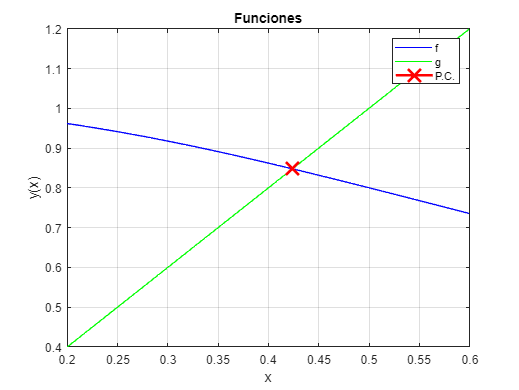

legend('f', 'g', 'P.C.')
xlabel("x")
ylabel("y(x)")
title("Funciones")
grid on
hold off

## Ejercicio Optimización

7.4 Given 

f (x) = −1.5x^6 − 2x^4 + 12x 

(a) Plot the function. 

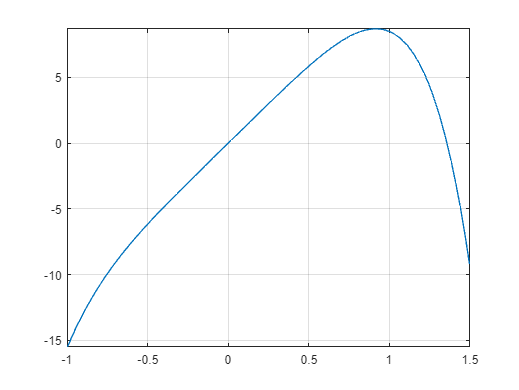

f = @(x) -1.5*x.^6-2*x.^4+12*x;

fplot(f,[-1 1.5])
grid on

(b) Use analytical methods to prove that the function is con­cave for all values of x. 

Si derivamos 2 veces, obtenemos que f''(x)=-45*x^4-24*x^2 la cuál siempre será negativa para toda x y por tanto f(x) es cóncava en todo su dominio. 

(c) Find the maximum f(x) and the corre­sponding value of x. 

g = @(x) -f(x);
%Máximos
[x3(1),i3(1)] = O1_proporcionAurea(g,.5,1.5);
[x3(2),i3(2)] = O2_newtonRaphsonMinimo(f,1);
[x3(3),i3(3)] = O3_IPS(f, .5, 1, 1.5)

x3 =     0.9169    0.9169    0.9169


i3 =     37     5     9
